## ECEN 415 Assignment 2

Niels Clayton: 300437590

### **Question 1.** 

A state space system is described by the system matrices:

clc;
clear;

A = [12.5314 , -91.36 , 28.7129 , 59.9628 ; 
     21.316 , -115.6631 , 37.5584 , 75.0519 ; 
     13.967 , -53.5817 , 15.4161 , 33.4391 ; 
     20.5222 , -123.3107 , 42.267 , 79.7156];
 
B = [1.7649 , 1.7649; 
     2.8318 , 2.8318; 
     2.2353 , 2.2353; 
     2.7294 , 2.7294];
 
C = [-0.46166 , -4.4635 , 1.9151 , 3.7274 ;
     1.0853 , -12.82 , 4.5753 , 8.3759];
 
D = [0 , 0 ; 
     0 , 0 ];

#### **(a)    **

If the system begins in a state $\mathit{\mathbf{x}}\left(0\right)={\left\lbrack 1\;\;\;\;1\;\;\;\;1\;\;\;\;2\right\rbrack }^T \;$, use matlab’s '`lsim``'` command to plot the response of the system in the time interval $t\in \left\lbrack 0,10\right\rbrack s$. You should plot the evolution of the system state $\left(\mathit{\mathbf{x}}\right)$ and its output $\left(\mathit{\mathbf{y}}\right)$ as a functions of time.

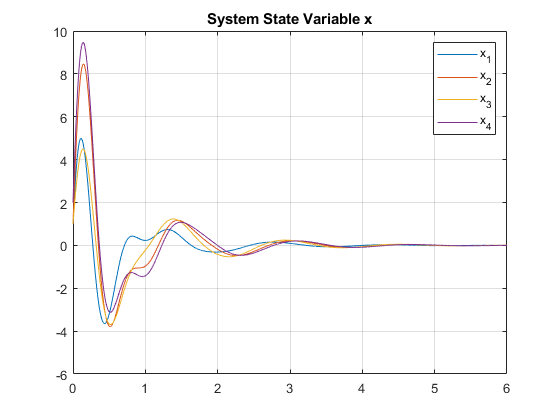

x_0 = [1, 1, 1, 2]';     % Initial System State

sys = ss(A, B, C, D);   % Create the system

t = 0:0.001:10;         % Setup the times series
u = zeros(length(t),2); % Generate steady state input

% Run the system simulation
[y, t, x] = lsim(sys, u, t, x_0);

plot(t, x);
title("System State Variable x");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("x_1", "x_2", "x_3", "x_4");
grid on;

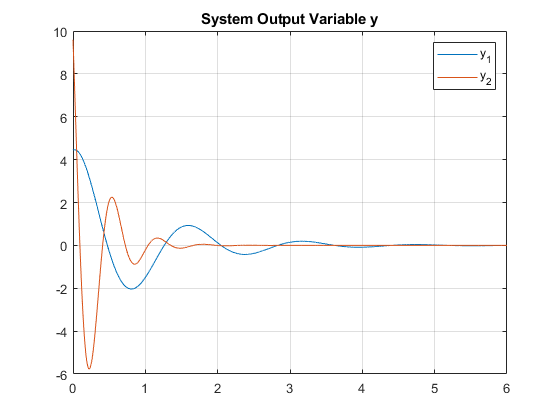


plot(t, y);
title("System Output Variable y");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("y_1", "y_2");
grid on;

#### (b)

Replicate the results from above using the matrix exponential to evolve the state, rather than '`lsim``'`

x_e = [];
y_e = [];

for t_ = 0:0.001:10
    xe = expm(t_*A)*x_0;
    ye = C*xe + D*[0; 0];
    
    x_e = [x_e; xe'];
    y_e = [y_e; ye'];
end

plot(t, x_e);
title("System State Variable x");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("x_1", "x_2", "x_3", "x_4");
grid on;


plot(t, y_e);
title("System Output Variable y");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("y_1", "y_2");
grid on;

#### (c) 

Use `lsim` to plot the response of the system to the input signal $\mathit{\mathbf{u}}={\left\lbrack u_1 \;\;\;\;u_2 \;\right\rbrack }^T$ with:


$$\begin{array}{l}
u_1 =u\left(t-1\right)\\
u_2 =2u\left(t-5\right)
\end{array}$$


for $u$ the (Heaviside) unit step function.

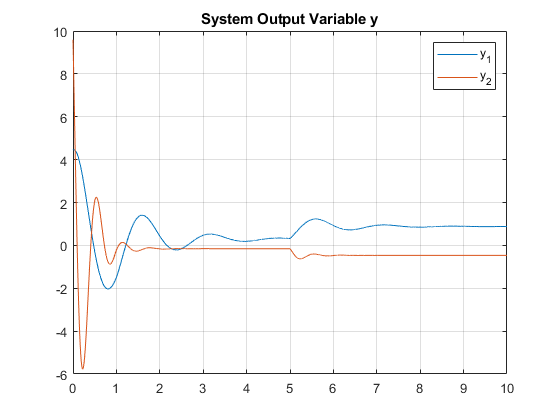

u = zeros(length(t),2); % Generate two seperate step inputs
u(t>1, 1) = 1;
u(t>5, 2) = 2;

% Run the system simulation
[y_h, t_h, x_h] = lsim(sys, u, t, x_0);

plot(t_h,y_h);
grid on;
title("System Output Variable y");
legend("y_1", "y_2");

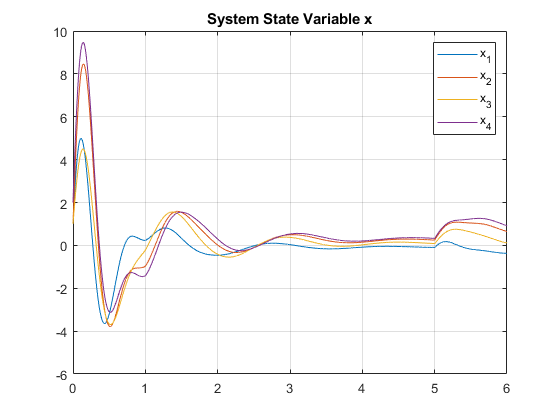

plot(t_h, x_h);
title("System State Variable x");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("x_1", "x_2", "x_3", "x_4");
grid on;

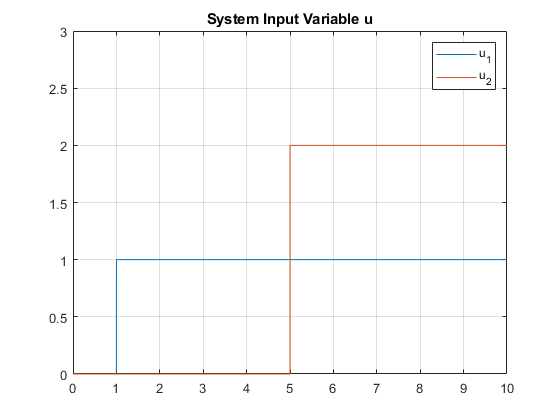


plot(t,u);
grid on;
ylim([0.00 3.00]);
title("System Input Variable u");
legend("u_1", "u_2");

#### (d)

Use `c2d` to discretize the system with an appropriate sampling frequency and use `lsim` to plot the response of the discrete time system.

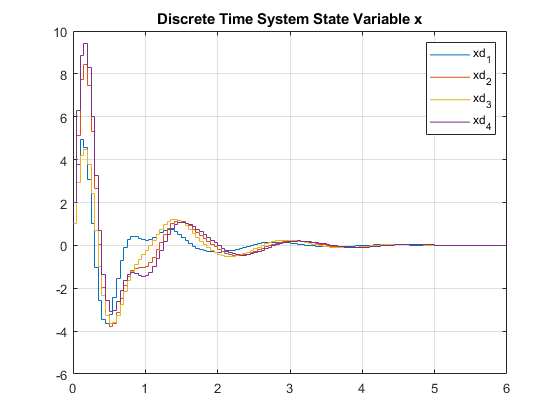

ts = 0.05;
td = 0:ts:10;
ud = zeros(length(td), 2);
sysd = c2d(sys, ts);

[yd, td, xd] = lsim(sysd, ud, td, x_0);

stairs(td, xd);
title("Discrete Time System State Variable x");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("xd_1", "xd_2", "xd_3", "xd_4");
grid on;

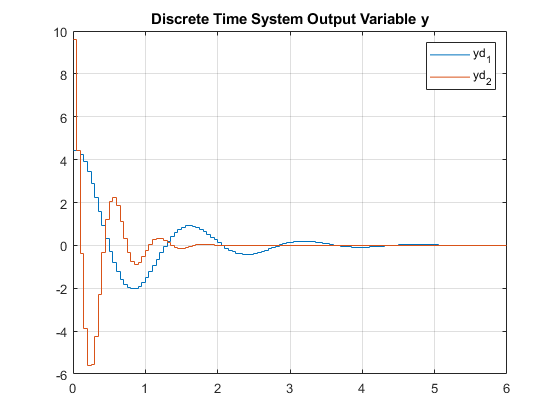


stairs(td,yd);
title("Discrete Time System Output Variable y");
xlim([0.00 6.00]);
ylim([-6.0 10.0]);
legend("yd_1", "yd_2");
grid on;

#### (e) 

Vary the sampling period and describe the effect on the output. 

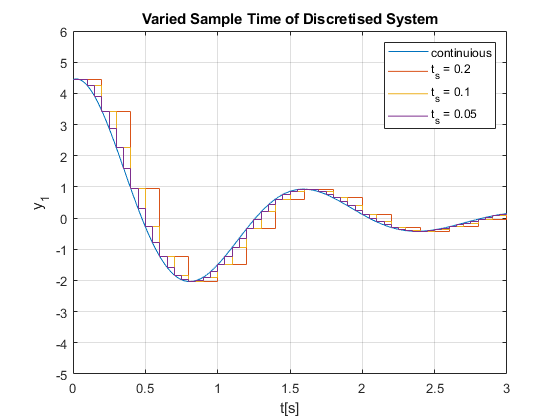

figure(1);
plot(t,y(:,1));
hold on

for ts = [0.2, 0.1, 0.05]
    td = 0:ts:10;
    ud = zeros(length(td), 2);
    sysd = c2d(sys, ts);
    
    [yd, td, xd] = lsim(sysd, ud, td, x_0);
    
    figure(1);
    stairs(td, yd(:,1));
end
hold off


figure(1);
title('Varied Sample Time of Discretised System');
xlim([0.00 3.00]);
ylim([-5.0 6.0]);
legend("continuious", "t_s = 0.2", "t_s = 0.1", "t_s = 0.05");
ylabel('y_1');
xlabel('t[s]');
grid on;

#### (f) 

Find the time response for the discrete time system if there is no input and initial conditions of $\mathit{\mathbf{x}}={\left\lbrack 1\;\;\;\;1\;\;\;\;1\;\;\;\;2\right\rbrack }^T$ . Determine this response using powers of $\mathit{\mathbf{A}}$ directly (ie, do not use lsim). 

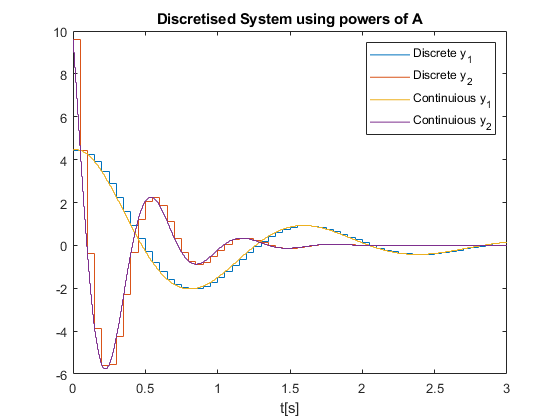

x_d = [];
y_d = [];

ts = 0.05;
td = 0:ts:10;
A_d = expm(ts*A);

for td_ = 0:ts:10
    xd = (A_d^(td_/ts))*x_0;
    yd = C*xd;
    
    x_d = [x_d; real(xd)'];
    y_d = [y_d; real(yd)'];
end

stairs(td, y_d)
hold on
stairs(t, y);
xlim([0.00 3.00]);
ylim([-6.0 10.0]);
title('Discretised System using powers of A');
legend("Discrete y_1", "Discrete y_2", "Continuious y_1", "Continuious y_2");
xlabel('t[s]');
hold off

### Question 2

% clc;
% clear;